# Miniprojekt 3 - Tone Control

## Indledning

Vi vil i denne opgave anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde med audiofiltre og algoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. I dette miniprojekt vil vi gøre brug af shelving filtre til at konstuere et tonekontrol for lavfrekvenser (bass) og højefrekvenser (treble).

## Formål

Vi vil analysere og designe en tonekontrol, som skal kunne ændre på gain af henholdsvis bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses på **figur XX** nedenfor.

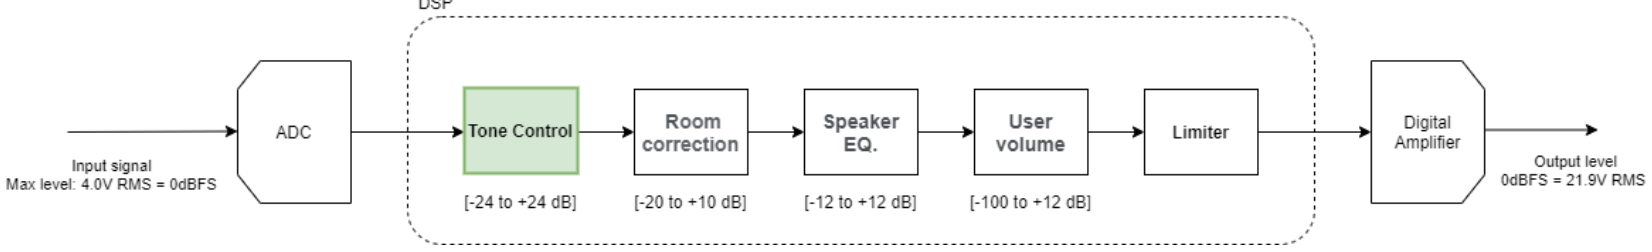

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade, hvor den ene er til bass og den anden til treble. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Den tonekontrol vi skal bygge bliver en simplificeret udgave af en equalizer med double band indeholdende cut og boost af inputsignalet. Det vil sige, at equalizere former af lydspektret ved at forbedre visse frekvens bands, mens andre forbliver upåvirket. Måden dette kan gøres på, er ved at bruge shelving filtre. Vi konstuere herved to shelving filtre og kaskade kobler dem. På denne måde får vi lavet et band for de lavefrekvenser, og et band for de højefrekvenser, derudover kommer der også et tilhørende band for de individuelle cut-off frekvenser.

Et 1. ordens shelving filter har et slope af frekvenskurven på 6 dB per octave **Kilde**, men i dette miniprojekt ønskes et større slope. Det vil sige stejler hældning, hvilket er hvorfor vi konsturere 2. ordens shelving filtre. Til konstuktionen af shelving IIR filtrene gøres brug af formlerne fra Table 2.3 se **figur XX**. Tabellen beskriver formlerne for de 3 "b" koeficienter og de 2 "a" koeficienter, da "a0" altid er 1. For at kunne bruge formlerne til koeficenterne skal "K" og "V0" beregnes, som der også ses formler til i Table 2.3 se **figur XX**.

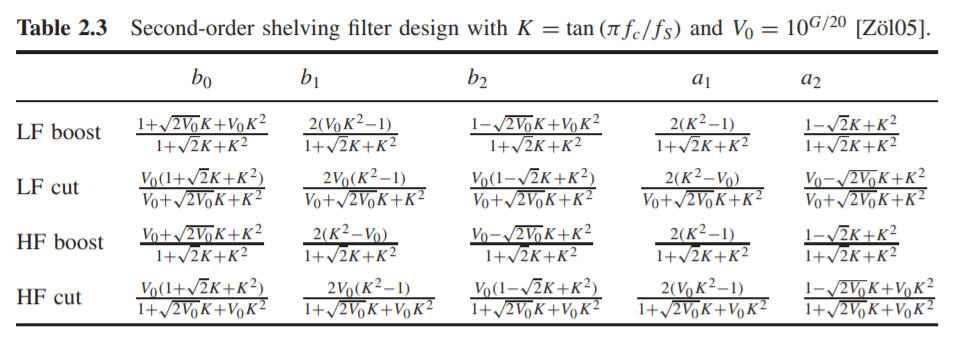

### Audio spectrum

Audio spectrum, også kaldet lydspektret er det hørbare frekvensområde for mennesker, som går fra 20 Hz til 20.000 Hz. I denne opgave bruges kun bass og treble, og vi vil derfor undersøge cut-off frekvenserne for disse områder. 

Ud fra **Kilde** har vi fundet cut-off til bass til at være 60 - 250 Hz, og treble til at være 4 - 6 kHz. Se **Figur XX**, for lydspektret ved alle områder.

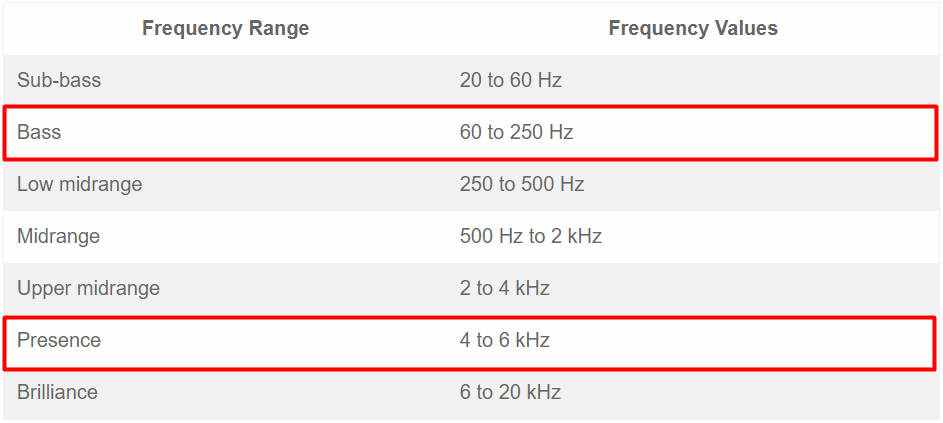

### *FilterSelect *funktion

For at producere vores filtre, vil vi lave en eksplicit funktion i matlab. Matlab funktionen vil blive vedhæftet som bilag.

Vi starter med at definere funktionen, og kalder den for *FilterSelect. *Den tager fire argumenter henholdsvis samplingfrekvens, gain af filtret, cut-off frekvens, og om det er et lavpas- eller højpasfilter. Funktionen returnere så B og A koefficienterne af IIR filtret.

K og V0 koefficienterne bestemmes som følgende.

%function [Bout,Aout] = FilterSelect(Fs, gain,Fc, sel)
%K = tan(pi*Fc/Fs);
%V0 = 10^(gain/20);

Nu skal filterkoefficienterne bestemmes. Det ses at nogle af nævnerne for beregningerne er gentagene, hvorfor disse kan pre-defineres.

%denomBoost = (1+sqrt(2)*K+K^2);
%denomCutLF = (V0+sqrt(2*V0)*K+K^2);
%denomCutHF = (1+sqrt(2*V0)*K+V0*K^2);

Først udvælges, om det er et filter for bass eller treble, hvilket gøres i den yderste if statement ud fra selector argumentet. Da der er forskellige koefficienter for hvis filteret skal booste eller cutte, laves der en indre if statement, der tjekker netop dette. Dette gøres ved at se på gain argumentet, da hvis denne er over eller under 0, er der tale om henholdsvis boost ellers cut. Er gain lig med 0, ved vi at filteret er fladt, og intet skal ændres ved signalet. Derfor er denne case taget med under boost if statementet.

%if(sel == "bass")
%    boost
%    if(gain >= 0)
%        b0=(1+sqrt(2*V0)*K+V0*K^2)/denomBoost;
%        b1=(2*(V0*K^2-1))/denomBoost;
%        b2=(1-sqrt(2*V0)*K+V0*K^2)/denomBoost;
%        a1=(2*(K^2-1))/denomBoost;
%        a2=((1-sqrt(2)*K+K^2))/denomBoost;
%        %cut
%    elseif (gain < 0)
%        b0=(V0*(1+sqrt(2)*K+K^2))/denomCutLF;
%        b1=(2*V0*(K^2-1))/denomCutLF;
%        b2=(V0*(1-sqrt(2)*K+K^2))/denomCutLF;
%        a1=(2*(K^2-V0))/denomCutLF;
%        a2=(V0-sqrt(2*V0)*K+K^2)/denomCutLF;
%    end
%elseif(sel == "treble")
%    boost
%    if(gain >= 0)
%        b0=(V0+sqrt(2*V0)*K+K^2)/denomBoost;
%        b1=(2*(K^2-V0))/denomBoost;
%        b2=(V0-sqrt(2*V0)*K+K^2)/denomBoost;
%        a1=(2*(K^2-1))/denomBoost;
%        a2=((1-sqrt(2)*K+K^2))/denomBoost;
%        %cut
%    elseif (gain < 0)
%        b0=(V0*(1+sqrt(2)*K+K^2))/denomCutHF;
%        b1=(2*V0*(K^2-1))/denomCutHF;
%        b2=(V0*(1-sqrt(2)*K+K^2))/denomCutHF;
%        a1=(2*(V0*K^2-1))/denomCutHF;
%        a2=(1-sqrt(2*V0)*K+V0*K^2)/denomCutHF;
%    end
%end

Når koefficienterne er fundet, kan de samles i hver deres array, og tildelses til retur værdierne for funktionen.

%Aout = [b0, b1, b2];
%Bout = [1, a1, a2];
%
%end

## Anvendelse af *Tonekontrol*

Nu vil vi anvende funktionen med et konkret eksempel.

%[x,Fs]=audioread("dinLydFil.mp3"); % Her kunne man eksempelvis uploade sin egen lydfil

Vi uploader lydfilen fra miniprojekt 1.

load("miniprojekt1_lydklip.mat"); % Her uploads en lydfil vi brugte i Miniprojekt 1

Der laves nu fire sliders til at justere henholdsvis cut-off for bass, cut-off for treble, gain for bass og gain for treble.

Fcb         = 150;      % Cutoff for bass
Fct         = 4500;    % Cutoff for treble

gainBass    =10;       % Gain for bass
gainTreble  =-6;       % Gain for treble

Med de ønskede parametre kan den skabte funktion (FilterSelect), nu anvendes til at frembringe filterkoefficienterne for de to filtre.

[Bbas,Abas] = FilterSelect(fs_s2,gainBass,Fcb,"bass");         % b og a koeffitienter for bass
[Btreb,Atreb] = FilterSelect(fs_s2,gainTreble,Fct,"treble");   % b og a koeffitienter for treble

Vi bruger nu følgende funktioner til at lave filtrene, og derefter kaskade koble de to filtre.

Nfft = 4096;                                % For at få flere data at arbejde med
Hbas = fft(Bbas,Nfft)./fft(Abas,Nfft);      % IIR filter for bass
Htreb = fft(Btreb,Nfft)./fft(Atreb,Nfft);   % IIR filter for treble
Hcas = Hbas.*Htreb;                         % Kaskadekobling af de to IIR filtre
Hcas = real(ifft(Hcas));                    % Ændring af kaskadekoblingen til tidsdomæne
y1 = filter(Bbas,Abas,s2);                  % Her påtrukkes bassfilteret på inputtet
y2 = filter(Btreb,Atreb,y1);                % Her påtrukkes treblefilteret på outputtet fra bassfilteret

Der er her lavet tre knapper, der kan anvendes til at afspille det filtrerede signal, det ufiltrerede signal og til at stoppe musikken.

 
soundsc(y2,fs_s2) % Det filtrerede signal

 
soundsc(s2,fs_s2) % Det ufiltrerede signal

 
clear sound % Stop musik

Her ses amplitude responset for det ønskede filter, og vi kan se at det sammen overens med de valgte parameter.

fvtool(Hcas, 'Analysis', 'magnitude', 'Fs', fs_s2); % Amplitude plot

Her ses fase responset for det ønskede filter, og vi kan se at der ikke er lineær fase.

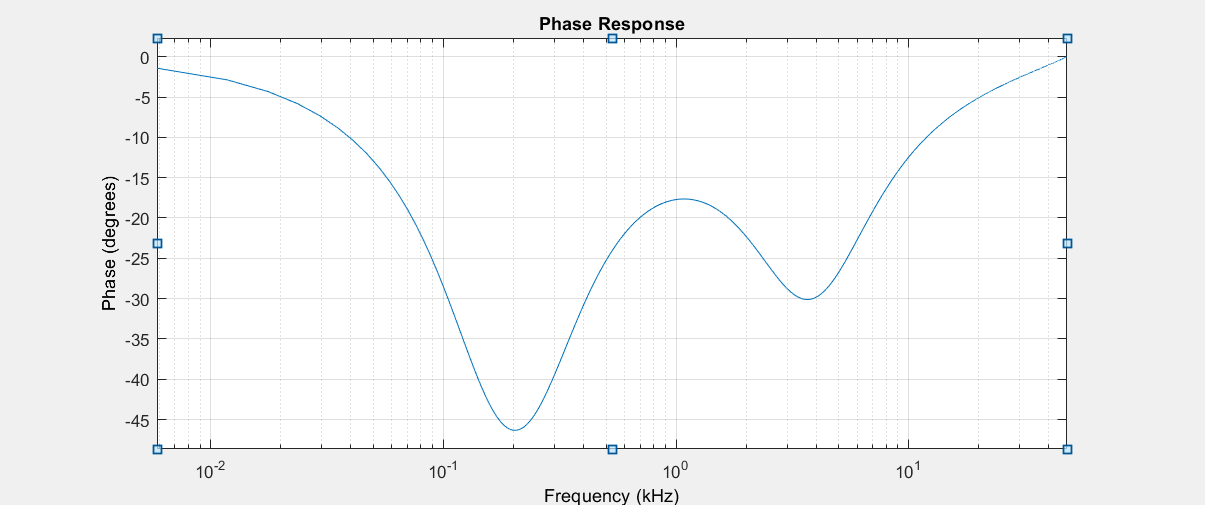

fvtool(Hcas, 'Analysis', 'phase', 'Fs', fs_s2); % Fase plot

Her ses impuls responset for det ønskede filter, og vi kan se at det er et IIR filter, fordi den forsætter uendeligt.

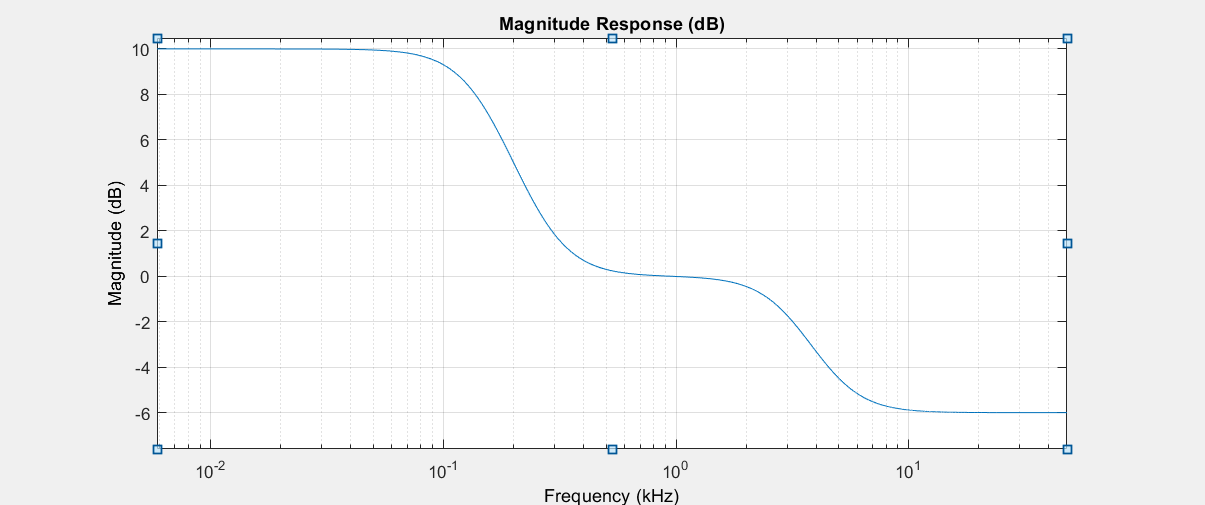

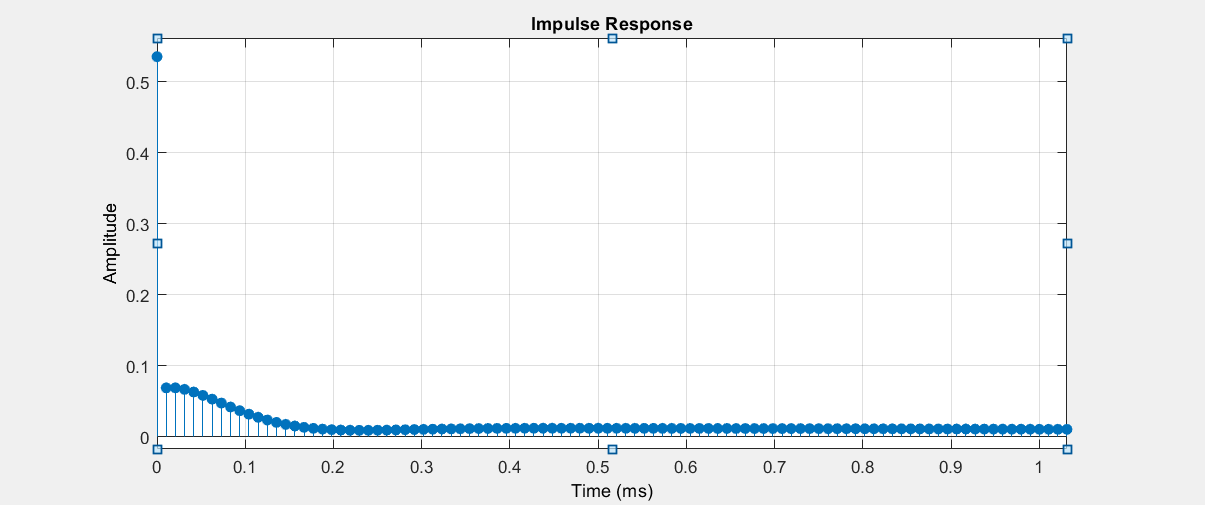

fvtool(Hcas, 'Analysis', 'impulse', 'Fs', fs_s2); % Impuls plot

## Konklusion

Vi har i denne opgave konstueret en tonekontrol til Lyngdorf TDAI-1120 forstærker. Dette er blevet udført ved at anvende 2. ordens shelving IIR filtre. Vi har skabt en filterfunktion, som kan genere "b" og "a" koefficenterne til filtrene ud fra ønskede parametre. Vi har udover funktionen, lavet et brugervenligt miljø til ændring af tonekontrol for treble og bass, med et konkret eksempel.